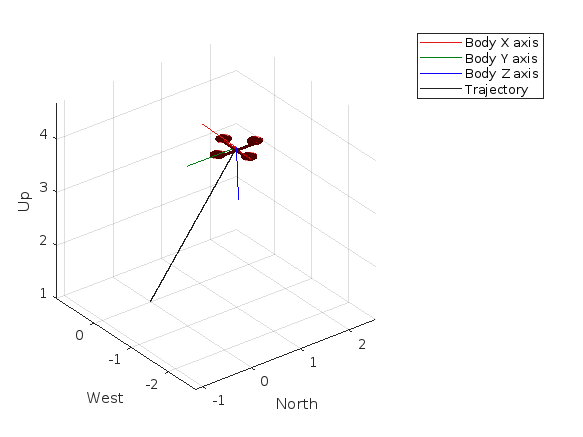

clear all;
close all;
clc;

modelName = 'tilting_control_voliro_template';

open_system(modelName);

% Simulation
simOut = sim(modelName);

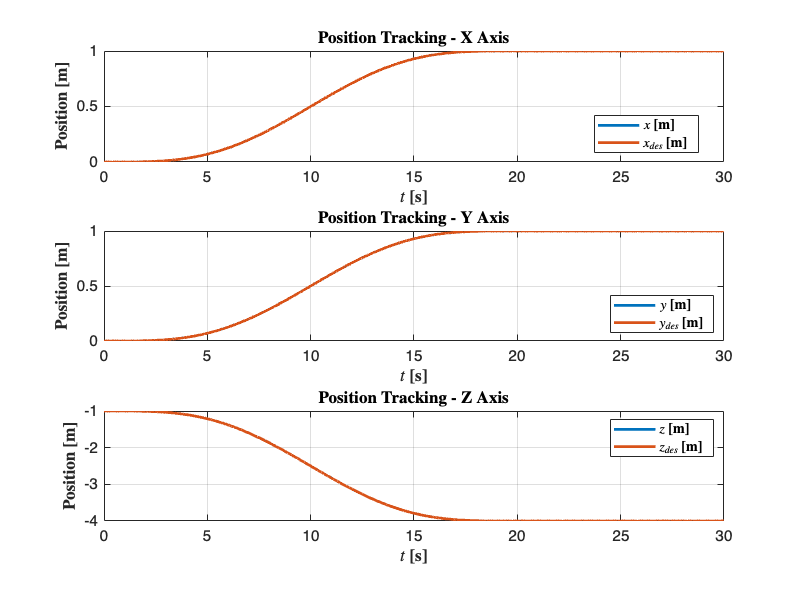


t = simOut.x.time;  
err_R = simOut.err_R.signals.values;
err_w = simOut.err_w.signals.values;
aplha = simOut.aplha.signals.values;
u_w = simOut.u_w.signals.values;
err_w = simOut.err_w.signals.values;
x = simOut.x.signals.values;
y = simOut.y.signals.values;
z = simOut.z.signals.values;
x_des = simOut.x_des.signals.values;
y_des = simOut.y_des.signals.values;
z_des = simOut.z_des.signals.values;
err_p = simOut.err_p.signals.values;
dot_err_p = simOut.dot_err_p.signals.values;
tau_b = simOut.tau_b.signals.values;
l_v = simOut.l_v.signals.values;
l_acc = simOut.l_acc.signals.values;
omega_bb = simOut.omega_bb.signals.values;

% Plot parameters
fontSize = 11;
titleSize = 12;
legendSize = 10;
lineWidth = 2;

% Figure 1: Position tracking (actual vs desired)
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, x, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, x_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$x$ [m]}', '\textbf{$x_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, y, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, y_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$y$ [m]}', '\textbf{$y_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, z, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot(t, z_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{Position Tracking - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Position [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$z$ [m]}', '\textbf{$z_{des}$ [m]}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);

saveas(gcf, 'position_tracking.eps', 'epsc');

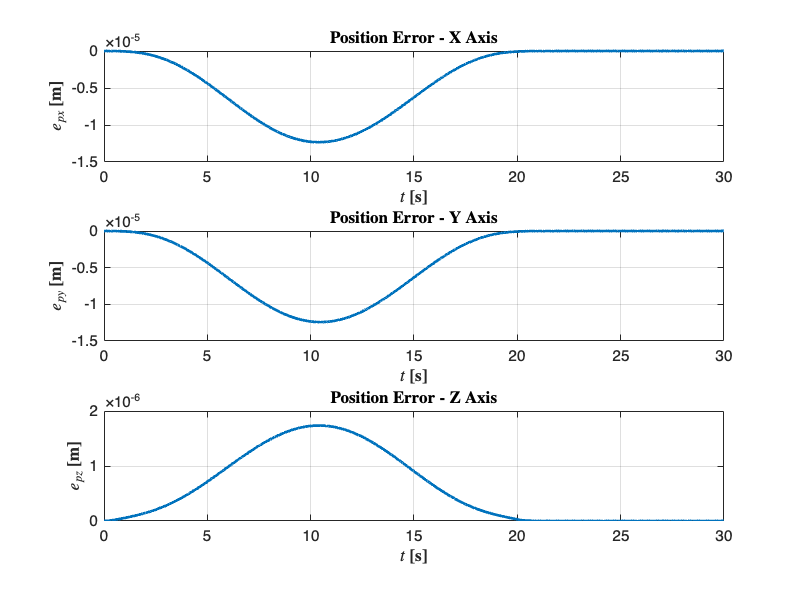


% Figure 2: Position errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_p(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{px}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_p(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{py}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_p(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Position Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{pz}$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'position_errors.eps', 'epsc');

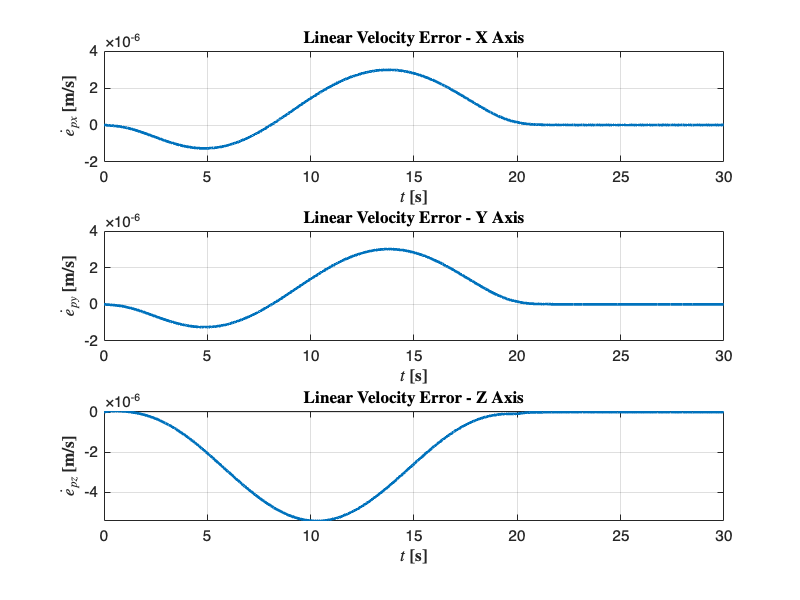


% Figure 3: Velocity errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, dot_err_p(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{px}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, dot_err_p(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{py}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, dot_err_p(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\dot{e}_{pz}$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'velocity_errors.eps', 'epsc');

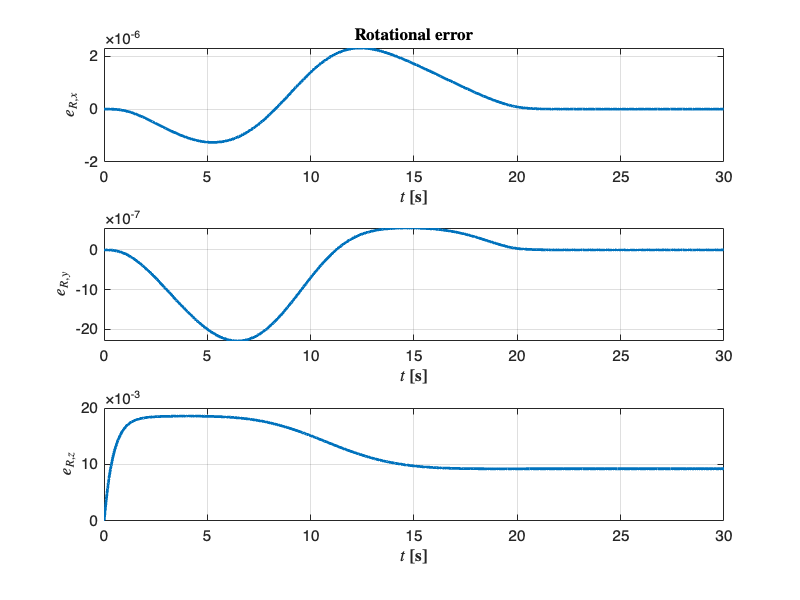


% Figure 4: Attitude errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_R(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotational error}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,x}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_R(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
%title('\textbf{Rotational error in SO(3)}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,y}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_R(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
%title('\textbf{Rotational error in SO(3)}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{R,z}$}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'rotational_errors.eps', 'epsc');

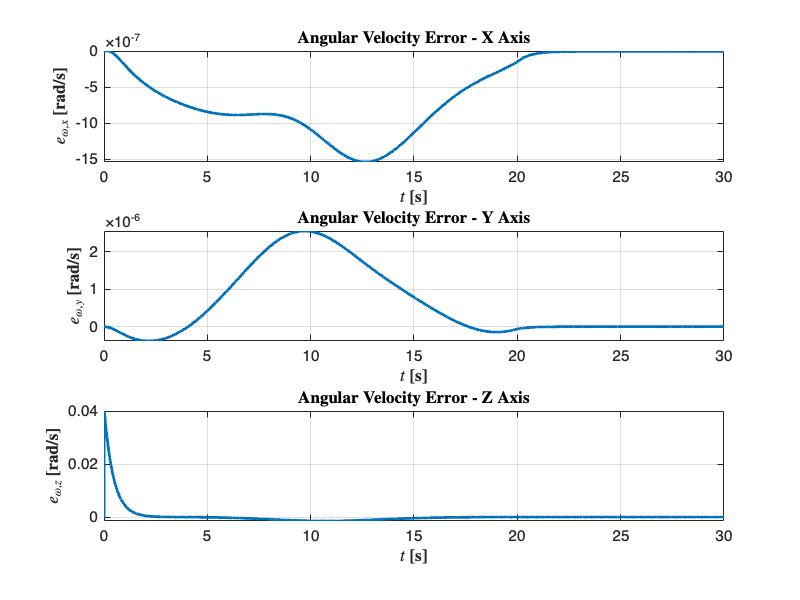


% Figure 5: Angular velocity errors
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, err_w(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,x}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, err_w(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,y}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, err_w(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity Error - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$e_{\omega,z}$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'angular_velocity_errors.eps', 'epsc');

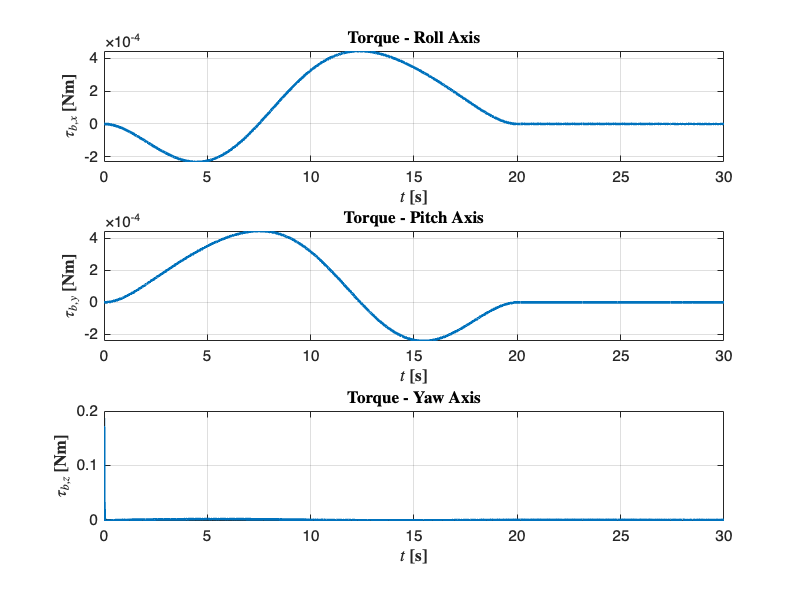


% Figure 6: Torques
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, tau_b(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Roll Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,x}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, tau_b(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Pitch Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,y}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, tau_b(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Torque - Yaw Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\tau_{b,z}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'torques.eps', 'epsc');

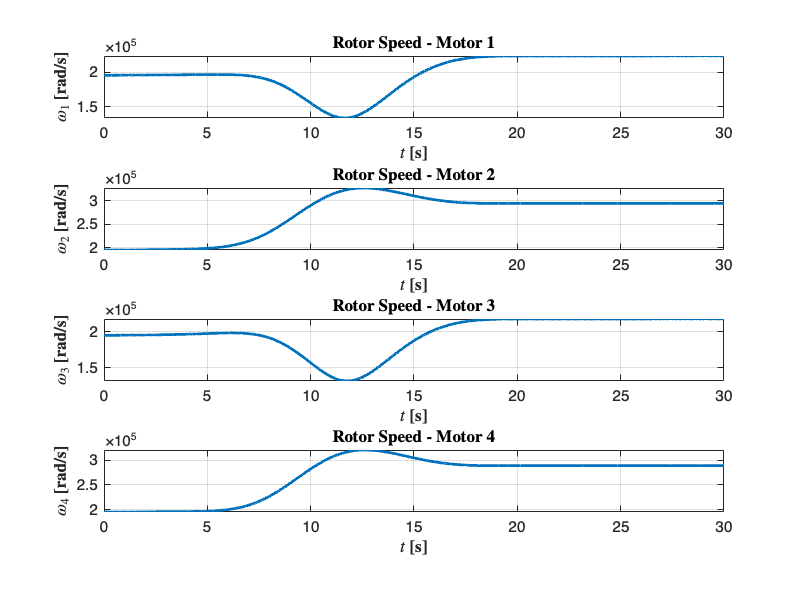


% Figure 7: Rotor speeds
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(4,1,1)
plot(t, u_w(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotor Speed - Motor 1}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_1$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,2)
plot(t, u_w(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotor Speed - Motor 2}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_2$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,3)
plot(t, u_w(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotor Speed - Motor 3}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_3$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,4)
plot(t, u_w(:,4), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Rotor Speed - Motor 4}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_4$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'rotor_speeds.eps', 'epsc');

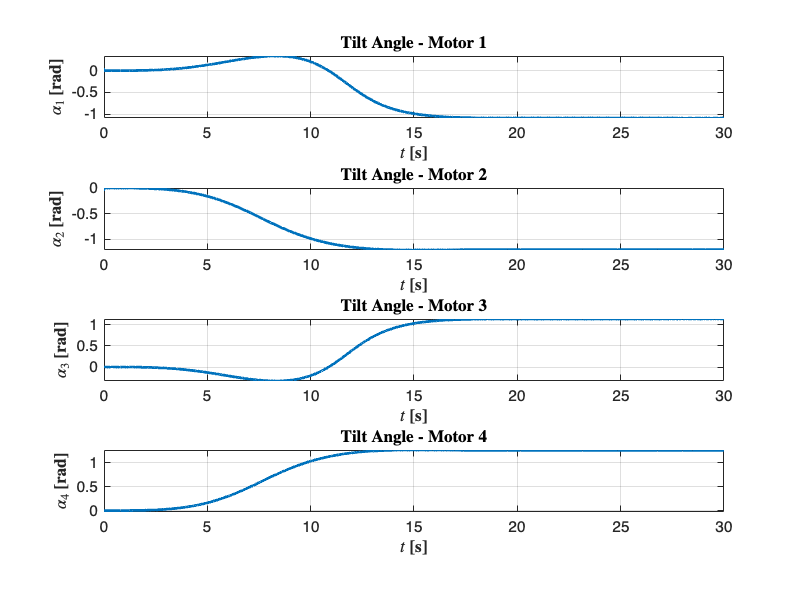


% Figure 8: Tilt angles
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(4,1,1)
plot(t, aplha(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Tilt Angle - Motor 1}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\alpha_1$ [rad]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,2)
plot(t, aplha(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Tilt Angle - Motor 2}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\alpha_2$ [rad]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,3)
plot(t, aplha(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Tilt Angle - Motor 3}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\alpha_3$ [rad]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(4,1,4)
plot(t, aplha(:,4), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Tilt Angle - Motor 4}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\alpha_4$ [rad]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'tilt_angles.eps', 'epsc');

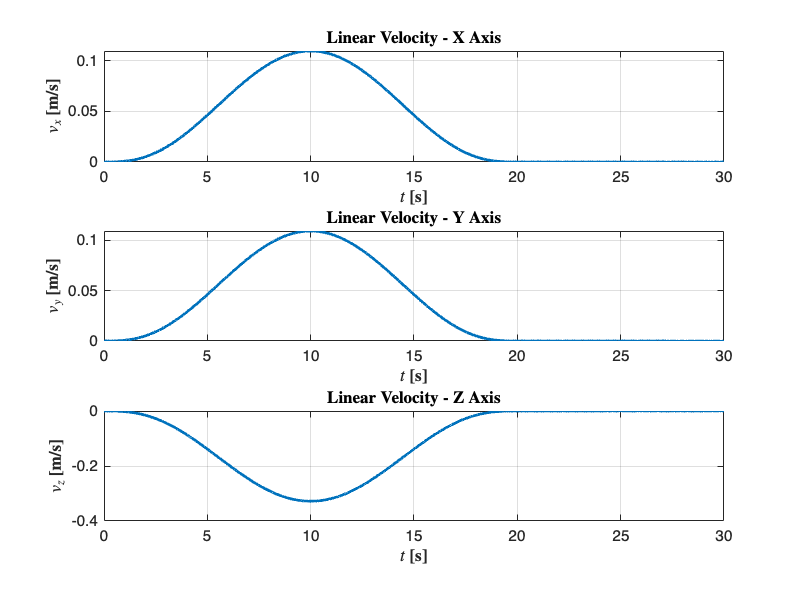


% Figure 9: Linear velocities
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, l_v(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$v_x$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, l_v(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$v_y$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, l_v(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Velocity - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$v_z$ [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'linear_velocities.eps', 'epsc');

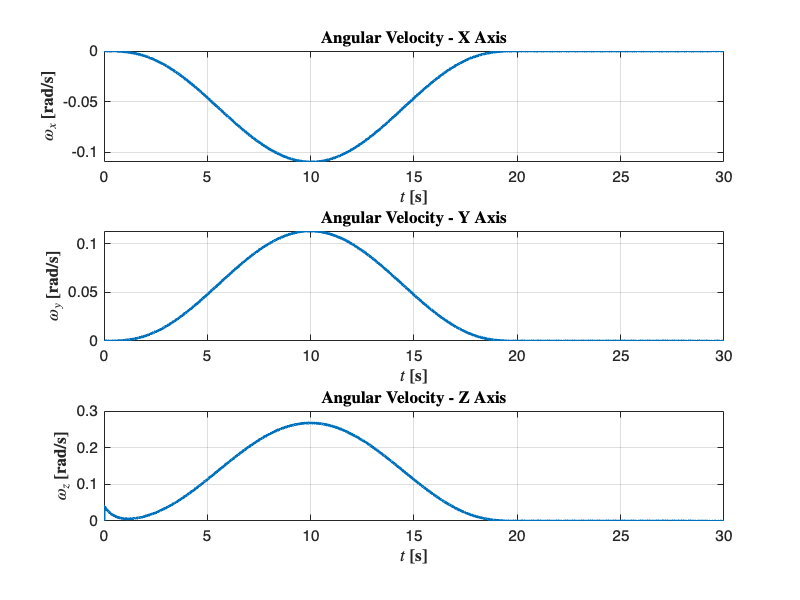


% Figure 10: Angular velocities
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, omega_bb(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_x$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, omega_bb(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_y$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, omega_bb(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Angular Velocity - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega_z$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'angular_velocities.eps', 'epsc');

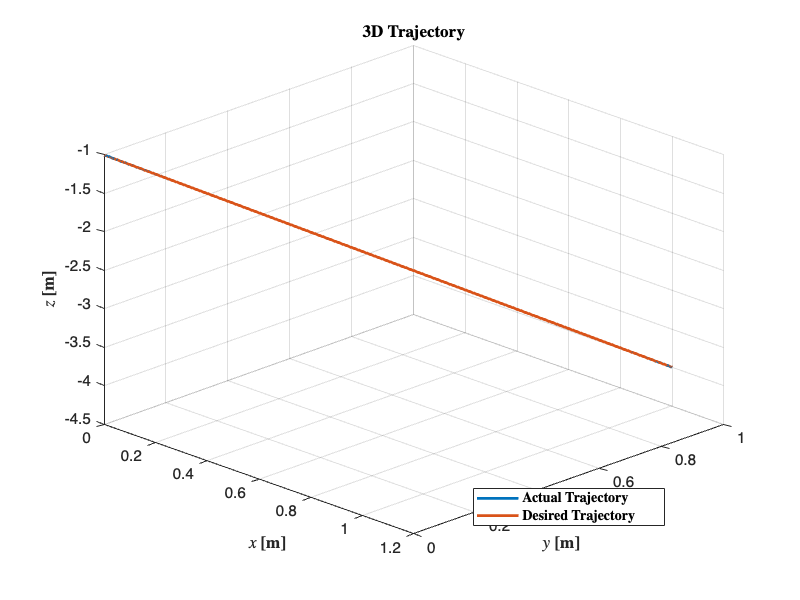


% Figure 11: 3D Trajectory
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

plot3(x, y, z, 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
hold on
plot3(x_des, y_des, z_des, 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', lineWidth)
title('\textbf{3D Trajectory}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
zlabel('\textbf{$z$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{Actual Trajectory}', '\textbf{Desired Trajectory}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
view(45, 30)
set(gca, 'FontSize', fontSize);

saveas(gcf, '3d_trajectory.eps', 'epsc');

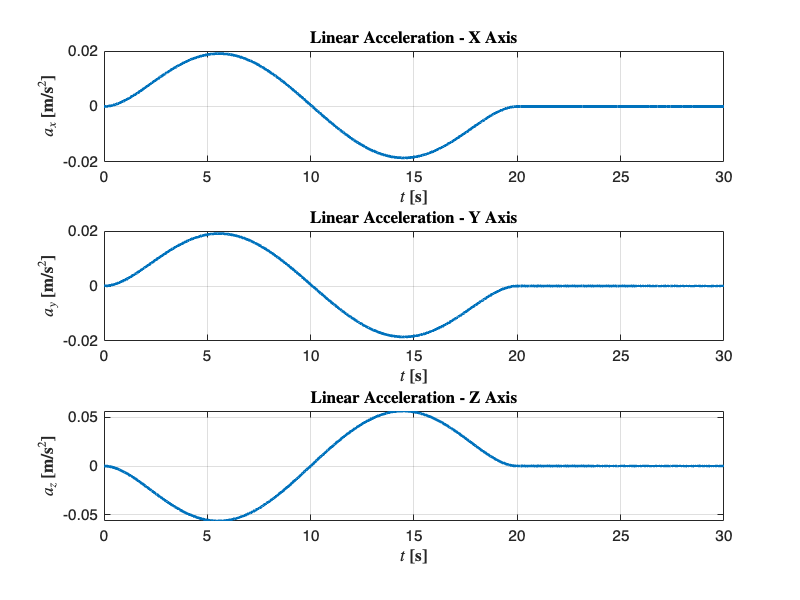


% Figure 12: Linear accelerations
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

subplot(3,1,1)
plot(t, l_acc(:,1), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Acceleration - X Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$a_x$ [m/s$^2$]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,2)
plot(t, l_acc(:,2), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Acceleration - Y Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$a_y$ [m/s$^2$]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

subplot(3,1,3)
plot(t, l_acc(:,3), 'Color', [0, 0.4470, 0.7410], 'LineWidth', lineWidth)
title('\textbf{Linear Acceleration - Z Axis}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$a_z$ [m/s$^2$]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);

saveas(gcf, 'linear_accelerations.eps', 'epsc');